# Laborator 07

## Probleme

## P1

format long
x=[1.3,1.6,1.9];
y=[0.6200860,0.4554022,0.2818186];
yd=[-0.5220232,-0.5698959,-0.5811571];
%calculăm tabele de diferențe divizate cu noduri duble
[z,T]=divdiffdn(x,y,yd);
t0=[1.5];
%aproximantele
z0=Newtonpol(T,z,t0);
fprintf("Tabela de diferente divizate:");

Tabela de diferente divizate:

disp(T);

   0.620086000000000  -0.522023200000000  -0.089742666666667   0.066365555555556   0.002666666666662  -0.002774691357989
   0.620086000000000  -0.548946000000000  -0.069833000000000   0.067965555555553   0.001001851851869                   0
   0.455402200000000  -0.569895900000000  -0.029053666666668   0.068566666666675                   0                   0
   0.455402200000000  -0.578612000000000  -0.008483666666665                   0                   0                   0
   0.281818600000000  -0.581157100000000                   0                   0                   0                   0
   0.281818600000000                   0                   0                   0                   0                   0



fprintf("Aproximanta Hermite:");

Aproximanta Hermite:

disp(z0);

   0.511827701728395



fprintf("A se verifica cu PDF-ul de la laborator");

A se verifica cu PDF-ul de la laborator

## P2

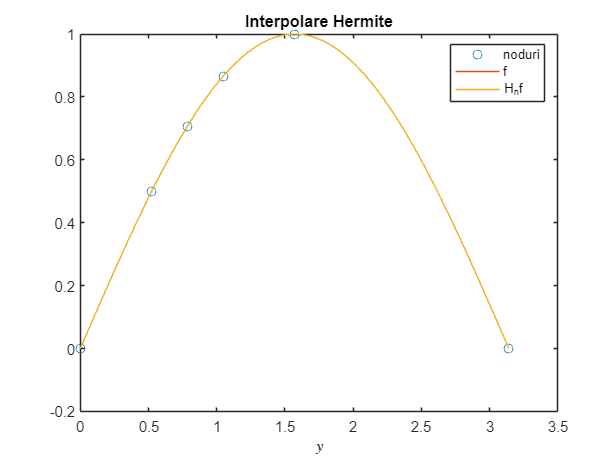

x=[0,pi/6,pi/4,pi/3,pi/2,pi];
y=sin(x);
yd=cos(x);
%calculăm tabele de diferențe divizate cu noduri duble
[z,T]=divdiffdn(x,y,yd);
t=linspace(0,pi,300);
zt=Newtonpol(T,z,t);
plot(x,y,'o',t,sin(t),t,zt)
legend('noduri','f','H_{n}f','Location','best');
xlabel('$x$','Interpreter','Latex')
xlabel('$y$','Interpreter','Latex')
title('Interpolare Hermite')

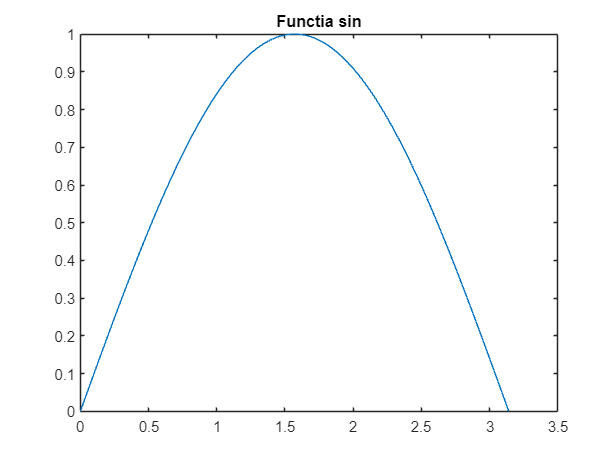

plot(t,sin(t));
title('Functia sin')
hold off

## P3

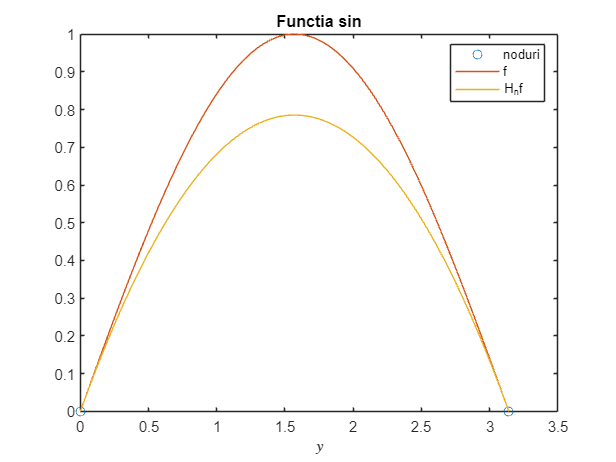

t0=[pi/2,pi/5,pi/7,pi/9];
z0 = CubH(0,pi,0,0,1,-1,t0,1,100);

fprintf("Aproximantele: ");

Aproximantele: 

disp(z0);

   0.785398163397448   0.502654824574367   0.384684814725281   0.310280755910103



## Probleme Practice

## P1

x = [0,1,2];
y = exp(x);
t = [0.25];
v = Lagrange(x,y,t);
fprintf("My Lagrange exp(0.25): %f",v);

My Lagrange exp(0.25): 1.152774

fprintf("MATLAB exp(0.25): %f",exp(t));

MATLAB exp(0.25): 1.284025

td=divdiff(x,y);
z=Newtonpol(td,x,t);
fprintf("My Hermite exp(0.25): %f",z);

My Hermite exp(0.25): 1.152774

## $$E_n(x) = \frac{f^{(n+1)}(\xi(x))}{(n+1)!} \times (x-x_0)(x-x_1)\cdots(x-x_n)$$  ==>> ERROR BOUND FORMULA

warning off
clear all 
syms x
interval = [0 2];
f(x)=exp(x);
f1 = @(x)exp(x)

f1 = function_handle with value:
    @(x)exp(x)


%f1_diff_6 = diff(f1,x,6)
f1_diff_6 = @(x)exp(x);
max_diff_6 = calculateMaximumForInterval(f1_diff_6,interval);
vals = [0 1 2];

f2 = @(x)(x-0)*(x-1)*(x-2);
max2 = calculateMaximumForInterval(f2,interval);

E2 = max_diff_6/factorial(3)*max2;
fprintf("My calculated Error: %f",E2);

My calculated Error: 0.473993

fprintf("My Error Bound: %f",round(E2,4));

My Error Bound: 0.474000


x = [0,1,2];
y = exp(x);
t = 0.25;
v = Lagrange(x,y,t);
td=divdiff(x,y);
z=Newtonpol(td,x,t);
actual_error = abs(eval(f(t)) - z);
fprintf("My Actual error : %f",actual_error);

My Actual error : 0.131251

## P2

x=[0.30,0.32,0.35];
y=[0.29552,0.31457,0.34290];
yd=[0.95534,0.94924,0.93937];
%calculăm tabele de diferențe divizate cu noduri duble
[z,T]=divdiffdn(x,y,yd);
t0=[0.34];
%aproximantele
z0=Newtonpol(T,z,t0);
fprintf("Aproximanta Hermite: %f",z0);

Aproximanta Hermite: 0.333489

fprintf("Matlab sin: %f", sin(0.34));

Matlab sin: 0.333487

## Error Bound

warning off
format long
clear all 
syms x
interval = [0.3 0.35];
f(x)=sin(x);
f1 = @(x)sin(x)

f1 = function_handle with value:
    @(x)sin(x)


%f1_diff_6 = diff(f1,x,6)
f1_diff_3 = @(x)-cos(x);
max_diff_3 = calculateMaximumForInterval(f1_diff_3,interval);
vals = [0.30,0.32,0.35];

f2 = @(x)(x-0.30)*(x-0.32)*(x-0.35);
max2 = calculateMaximumForInterval(f2,interval);

E2 = max_diff_3/factorial(3)*max2;
fprintf("My calculated Error: %f",E2);

My calculated Error: -0.000001

fprintf("My Error Bound: %f",round(E2,4));

My Error Bound: -0.000000


x=[0.30,0.32,0.35];
y=[0.29552,0.31457,0.34290];
yd=[0.95534,0.94924,0.93937];
%calculăm tabele de diferențe divizate cu noduri duble
[z,T]=divdiffdn(x,y,yd);
t0=0.34;
%aproximantele
z0=Newtonpol(T,z,t0);
actual_error = eval(f(t0)) - z0;
fprintf("My Actual error : %f",actual_error);

My Actual error : -0.000002

## Adaugam info pt 0.33

x=[0.30,0.32,0.33,0.35];
y=[0.29552,0.31457,sin(0.33),0.34290];
yd=[0.95534,0.94924,cos(0.33),0.93937];
%calculăm tabele de diferențe divizate cu noduri duble
[z,T]=divdiffdn(x,y,yd);
t0=[0.34];
%aproximantele
z0=Newtonpol(T,z,t0);
fprintf("Aproximanta Hermite: %f",z0);

Aproximanta Hermite: 0.333494

fprintf("Matlab sin: %f", sin(0.34));

Matlab sin: 0.333487

## Error Bound

warning off
format long
clear all 
syms x
interval = [0.3 0.35];
f(x)=sin(x);
f1 = @(x)sin(x)

f1 = function_handle with value:
    @(x)sin(x)


%f1_diff_6 = diff(f1,x,6)
f1_diff_4 = @(x)-cos(x);
max_diff_4 = calculateMaximumForInterval(f1_diff_4,interval);
vals = [0.30,0.32,sin(0.33),0.35];

f2 = @(x)(x-0.30)*(x-0.32)*(x-0.33)*(x-0.35);
max2 = calculateMaximumForInterval(f2,interval);

E2 = max_diff_4/factorial(4)*max2;
fprintf("My calculated Error: %f",E2);

My calculated Error: -0.000000

fprintf("My Error Bound: %f",round(E2,4));

My Error Bound: -0.000000


x=[0.30,0.32,0.33,0.35];
y=[0.29552,0.31457,sin(0.33),0.34290];
yd=[0.95534,0.94924,cos(0.33),0.93937];
%calculăm tabele de diferențe divizate cu noduri duble
[z,T]=divdiffdn(x,y,yd);
t0=0.34;
%aproximantele
z0=Newtonpol(T,z,t0);
actual_error = eval(f(t0)) - z0;
fprintf("My Actual error : %f",actual_error);

My Actual error : -0.000007

## P3

timpi = [0, 3, 5, 8, 13]; % x
distante = [0, 225, 383, 623, 993]; % y
viteze = [75, 77, 80, 74, 72]; % yd
[z,T]=divdiffdn(timpi,distante,viteze);
t0=[10];
%aproximantele
z0=Newtonpol(T,z,t0);
fprintf("Distanta: %f",z0);

Distanta: 742.502839

fprintf("Viteza: %f",z0/t0);

Viteza: 74.250284